# **Bayesian Optimisation Example**

**SECTION 1.0**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

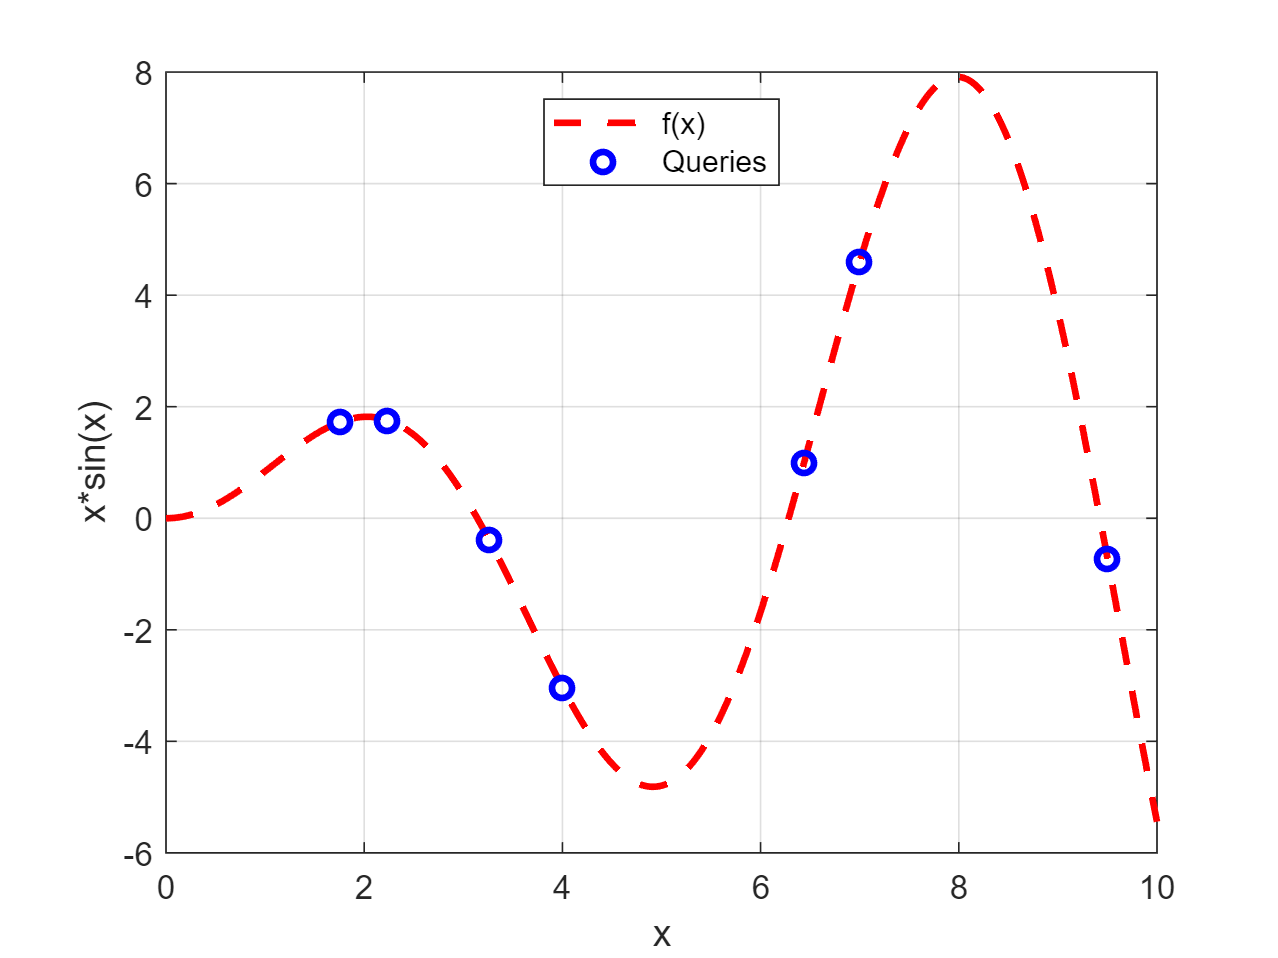

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x" );
ylabel( "x*sin(x)" );
legend( "f(x)", "Queries", "Location", "north")

**SECTION 2.0**

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the Upper Confidence Bound acquisition function

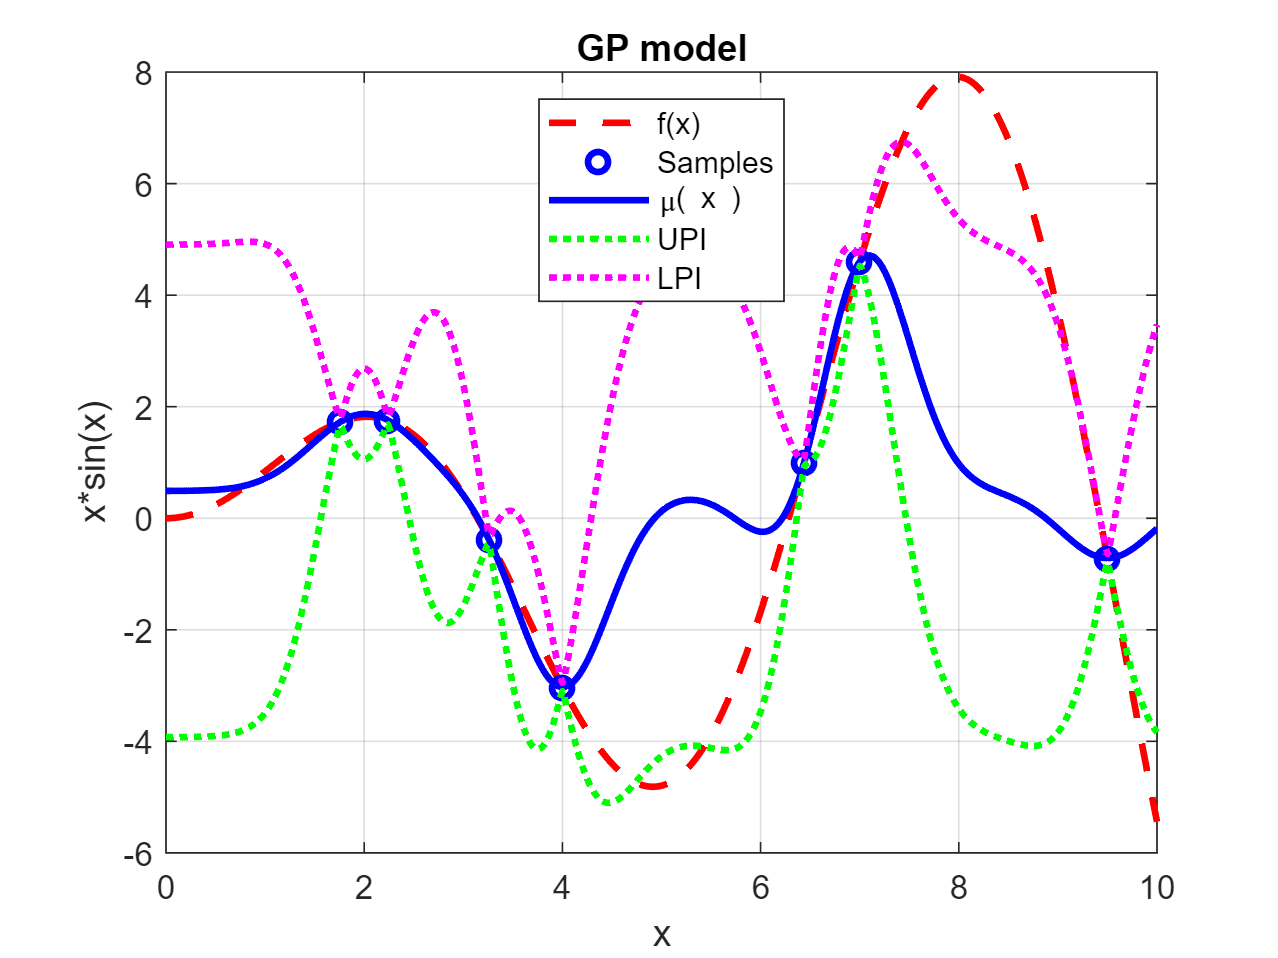

B = bayesOpt( "gpr", "aei");
B = B.conDataCoding( 0, 10 );
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north');

**SECTION 3.0**

Minimise -UCB(x)

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -1.510724e-02    0.000e+00    1.195e+00
    1       4   -3.601894e-02    0.000e+00    4.446e-02    1.195e+00
    2       6   -3.810779e-02    0.000e+00    5.338e-02    4.286e-02
    3       8   -6.451768e-02    0.000e+00    1.755e-01    2.573e-01
    4      13   -3.188338e-01    0.000e+00    4.382e-01    5.289e-01
    5      22   -4.008243e-01    0.000e+00    4.706e-01    1.322e-01
    6      24   -4.153001e-01    0.000e+00    2.231e-02    6.847e-02
    7      26   -4.153398e-01    0.000e+00    3.291e-03    3.099e-03
    8      28   -4.153407e-01    0.000e+00    3.153e-05    5.363e-04
    9      30   -4.153407e-01    0.000e+00    4.849e-08    5.088e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

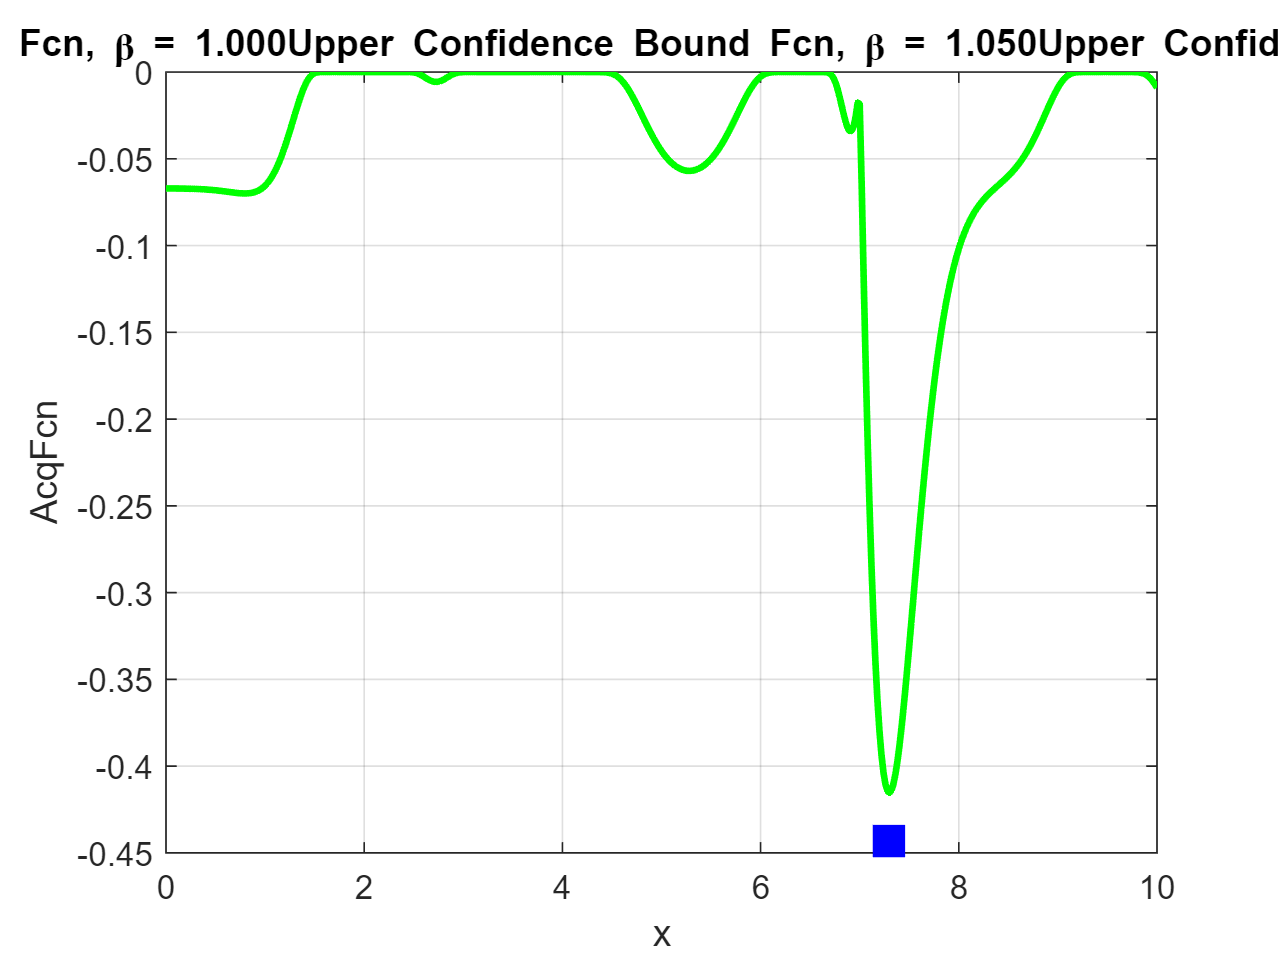

U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

**SECTION 4.0**

Query f(x) at the suggested value and update the GP model

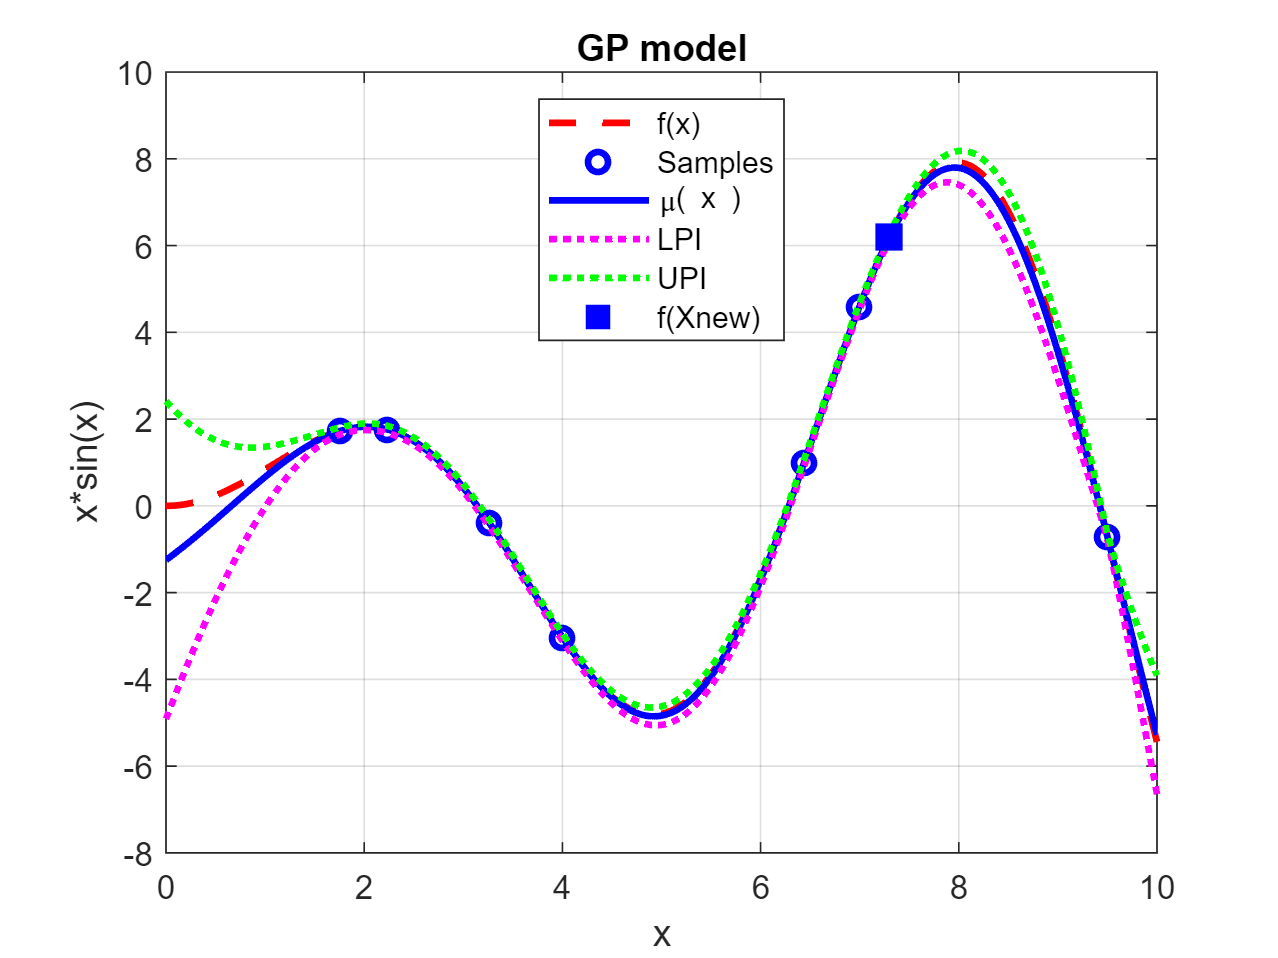

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

**SECTION 5.0**

Iteration 2. Now re-optimise the acquisition function and add the new query to the training data and retrain the surrogate model.

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -1.242190e-02    0.000e+00    1.958e+00
    1       5   -1.173964e+00    0.000e+00    2.635e+00    9.792e-01
    2       7   -1.372717e+00    0.000e+00    1.870e+00    5.617e-01
    3       9   -1.598936e+00    0.000e+00    4.709e-02    2.332e-01
    4      11   -1.599074e+00    0.000e+00    1.576e-03    6.024e-03
    5      13   -1.599074e+00    0.000e+00    1.439e-06    1.951e-04
    6      17   -1.599074e+00    0.000e+00    0.000e+00    4.455e-08

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

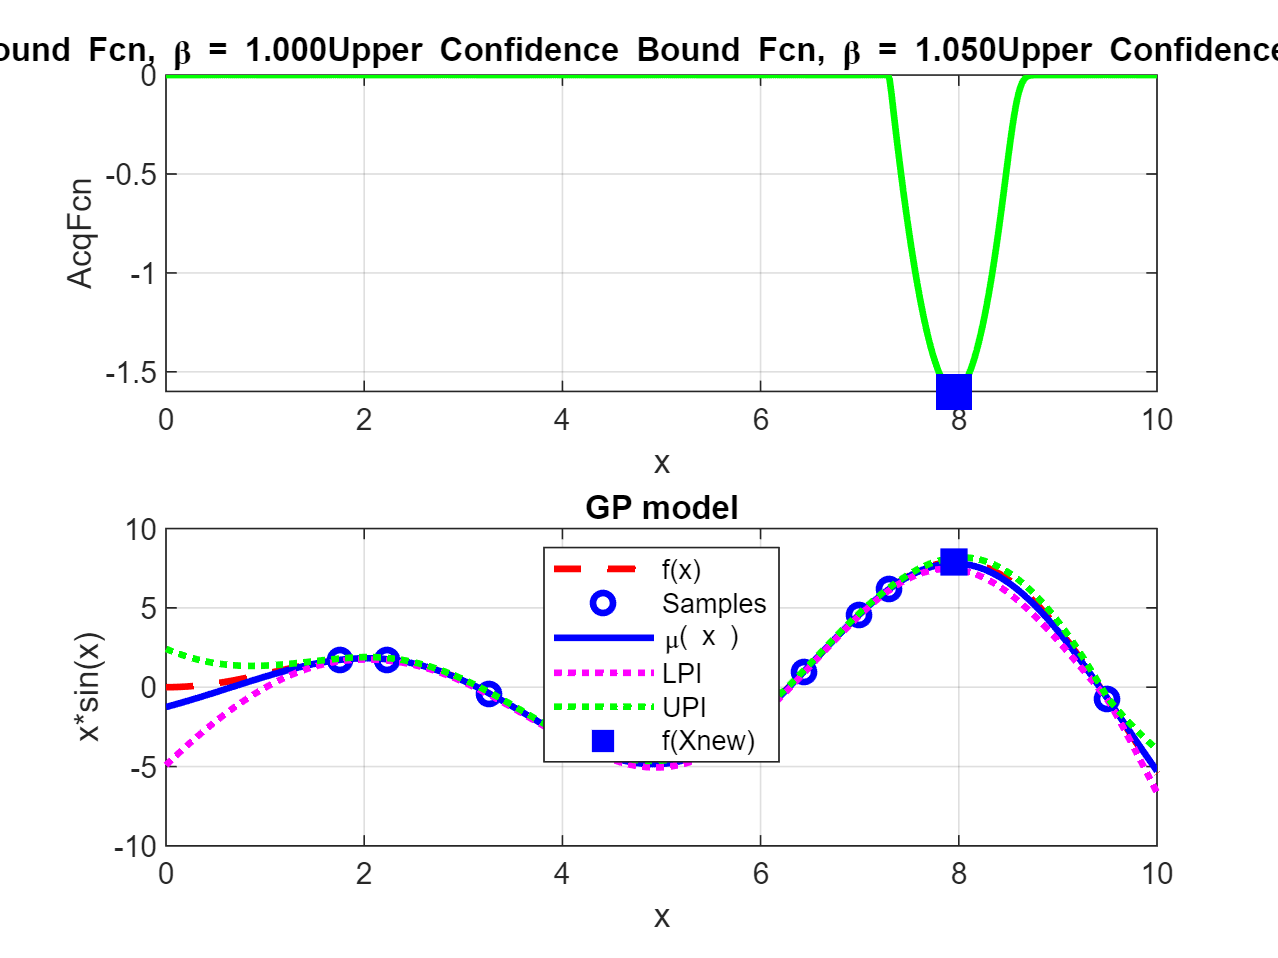

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', B.X, B.Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");